## [ACCELOPRINT BEAM BENDING REVERSE SOLVER]

# **Set-Up**

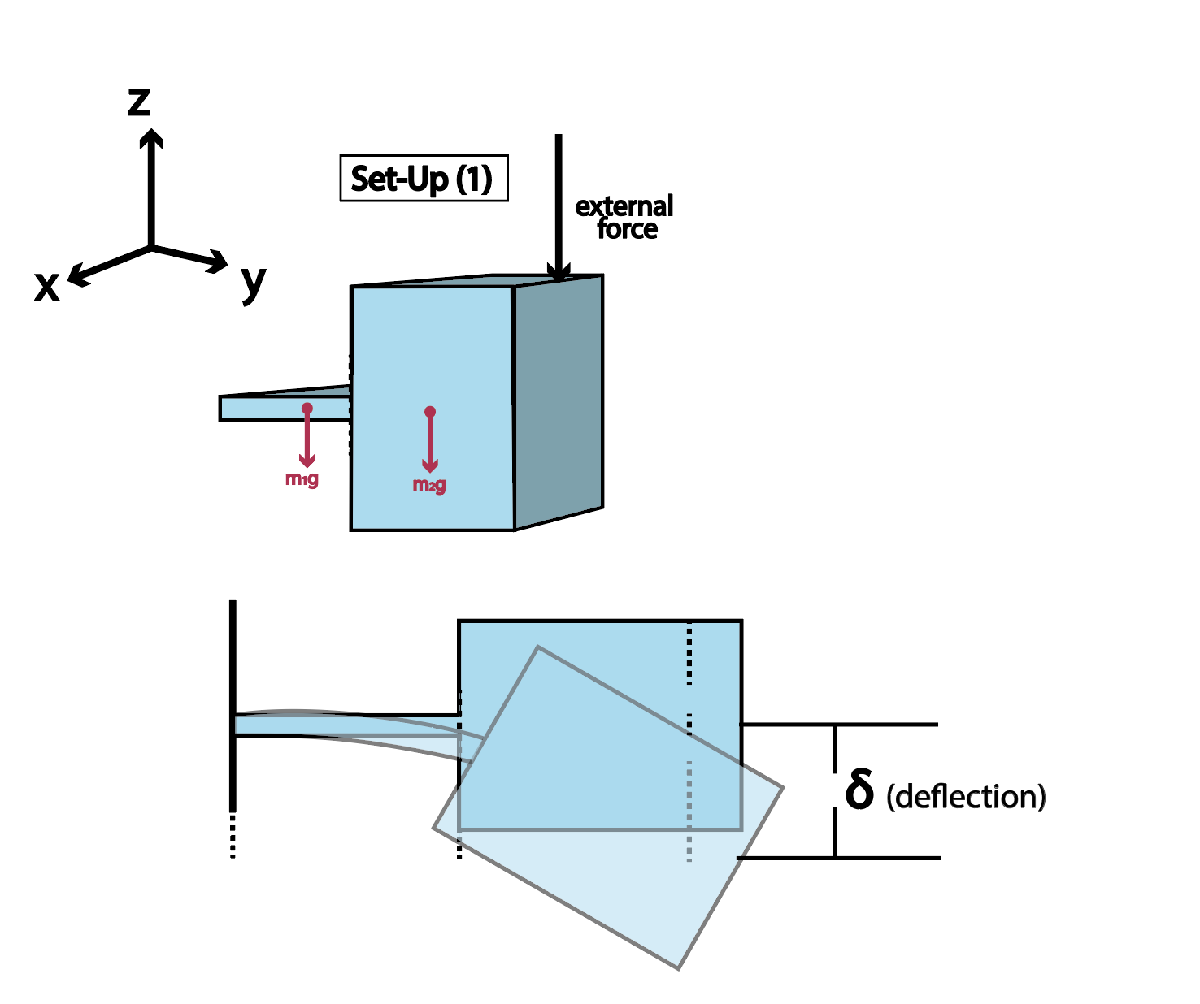

# **Assumptions **

`1) shearing is negligible of material`

`2) No plastic deformation/ yield upon loading unloading (though limits must be calculated)`

`3) E of the material is constant (not true for 3D prints due to anisotropic properties) `

`4) Density is for prints with 100% infill- otherwise, put a fraction next to density value`

`5) Static loading `

# **Goal **

1) Amount of Deflection is constant (an INPUT)

2) Another Input is g-force (acceleration) 

3) Output is the length of the cantilever beam 

4) All other geometrical inputs are constant or fixed

# **INPUTS**

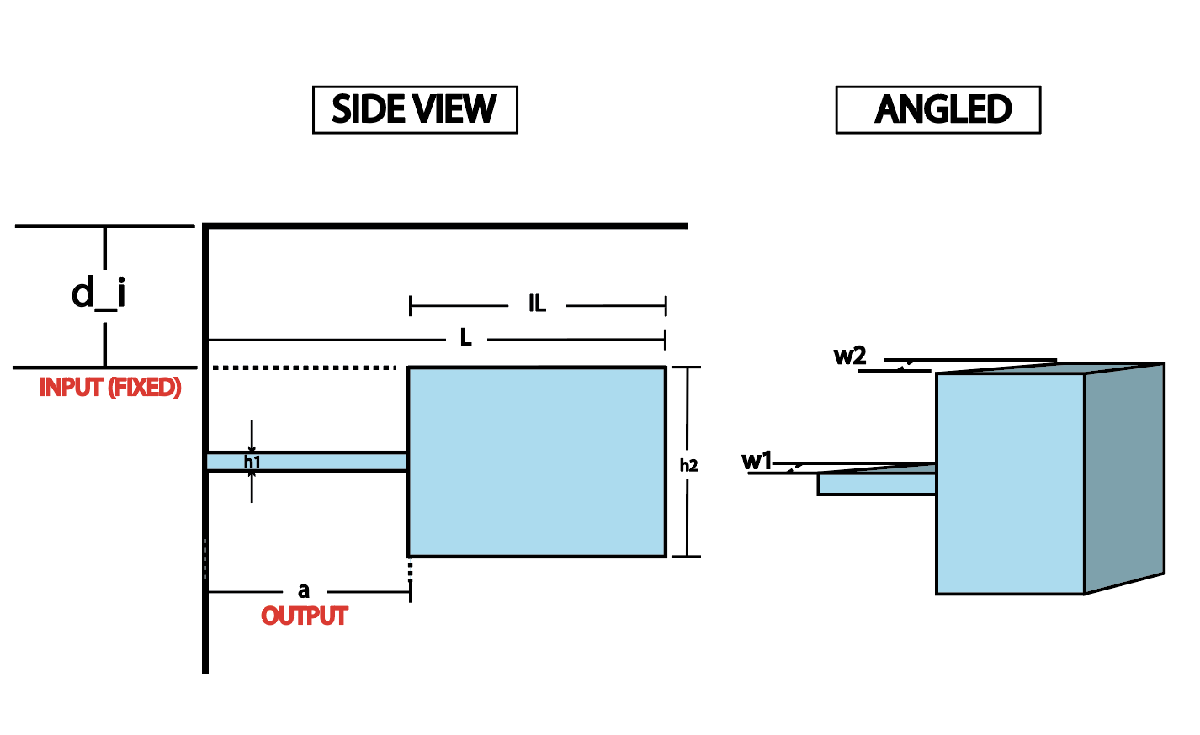

clear all %clear all previous solutions

## **Material properties (*****TPU and PLA*****)**


E_TPU= 26* 10^6; %Young Modulus (Pascal) 
E_PLA= 3250 * 10^6; %Young Modulus (Pascal) -- taken for Ultimaker PLA
E_cPLA=  10.7*10^6;  

rho_PLA= 1240; %PLA density in Kg/m^3
rho_TPU= 1235; %TPU density in Kg/m^3

E= E_cPLA;
rho= rho_PLA;


## **Geometry **

%%Lengths [default or Fixed]%%

IL= 17.5 *10^-3; %meters, length of swinging mass


%%Widths [default or Fixed]%%

w1= 0.4*10^-3; %meter, width of the cantilever beam
w2= 0.4*10^-3; %meters, width of the swinging mass

%%Heights [default or Fixed]%%

h1= 3*10^-3;%meters, thickness of the cantilever beam.
h2= 8.5*10^-3; %meters, thickness of the swinging mass 


## **Masses (known ONLY) **


% Masses % 

m2= rho*h2*w2*(IL); %mass of swinging mass


## **Acceleration**

acc= 10; %m/s^2 %input acceleration or"g-force"
g= 9.81; %m/s^2 "gravitational acceleration constant"
 

## **Deflection **


%%deflection [default or Fixed]%%

d_i= 1.25 *10^-3; %meters, distance from the swinging mass's end to the frame of Acceloprint
Deflection_endmass= d_i+h2/2; %meters, deflection from neutral axis (the one we get from solving equations with)

## Moment of Inertias 

I1= MomentInertia(w1, h1); %moment of inertia of cantilever beam
I2= MomentInertia(w2, h2); %moment of inertia swinging mass

# Equations for reaction forces and moments 

Since this is a cantilever beam problem, the Free body diagram (with reaction forces) looks like the picture below. There are both reaction moments and reaction forces at the position (y=0). Which we calculate and find expressions for in this section. 

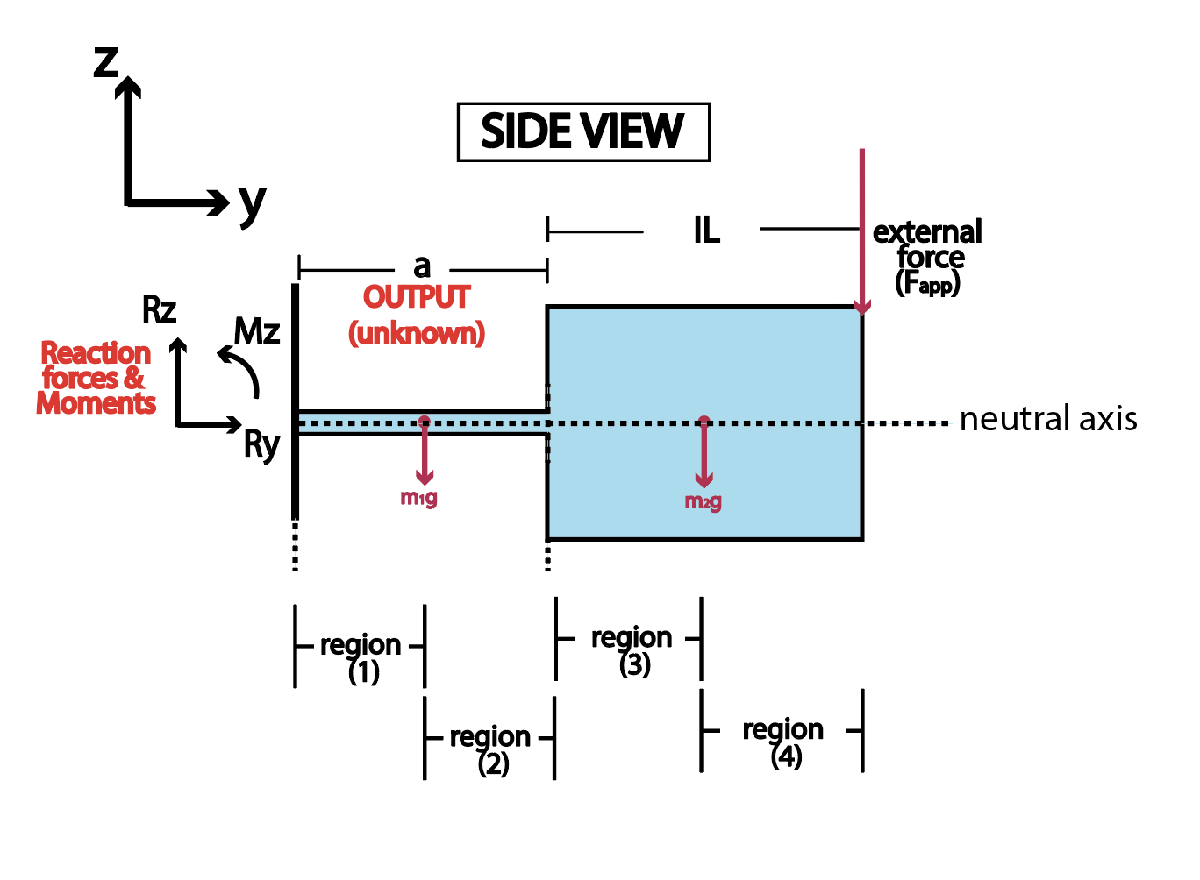

How we solve is based on static loading condition assumption (F_total=0, M_total=0)


 %z loading reaction force %
syms  a y  
m1= rho*h1*w1*a; %mass of the cantilever rod (without the end mass)
Fapp= (m1+m2)*acc; %applied force at the end mass
Rz(a)= m1*g+ m2*g + Fapp; %reaction force at the fixed end of the cantilever (y=0)
MR(a)= (m1*g*a/2)+ m2*g*(a+IL/2)+Fapp*(a+IL); %reaction moment at the fixed end of the cantilever (y=0)

# Region (1) -- (region from 0<y<a/2)--

##  Prior to the center of mass force on cantilever beam

We solve here for deflection at end of region (1) which is used as end condition for region (2)


v_1= Rz(a); %force at y
Mz_1(y)= y*v_1-MR(a); %moment at y

%We next double integrate to get the deflection in region(1)%%

C1_r1= 0 ; %initial condition for slope
C2_r1= 0;  %initial condition for deflection

fr1(y)= Mz_1(y)/(E*I1); %Euler-Bernouille Equation Left-hand-side equation
slope_r1 (y)= int(fr1,y) +C1_r1; %First integration of Euler-Bernouilli


deflection_r1(y)= int(slope_r1,y) +C2_r1;%Second integration of Euler-Bernouilli to get deflection

# Region (2) -- (region from a/2<y<a) -- 

## ie, After the center of mass force on cantilever beam AND before the change in cross section (ie from cantilever beam to swinging mass)

We solve here for deflection at end of region (2) which is used as end condition for region (3)


C1_r2= slope_r1 (a/2); %initial condition for slope at a/2
C2_r2= deflection_r1(a/2); %initial condition for deflection at a/2

v_2= Rz(a)-m1*g;  %force at y
Mz_2(y)= v_2*y+m1*g*(a/2)-MR(a); %moment at y

fr2(y)= Mz_2(y)/(E*I1); %Euler-Bernouille Equation Left-hand-side equation
slope_r2(y)= int(fr2,y) +C1_r2; %First integration of Euler-Bernouilli


deflection_r2(y)= int(slope_r2,y) +C2_r2;%Second integration of Euler-Bernouilli

# Region (3) -- (region from a<y<a+IL/2)

##  Prior to the center of mass force on the swinging mass

We solve here for deflection at end of region (3) which is used as end condition for region (4)


C1_r3= slope_r2 (a); %initial condition for slope at a
C2_r3= deflection_r2(a); %initial condition for deflection at a

v_3= Rz(a)-m1*g;  %force at y
Mz_3(y)= v_3*y+m1*g*(a/2)-MR(a);  %moment at y

fr3(y)= Mz_3(y)/(E*I2); %Euler-Bernouille Equation Left-hand-side equation
slope_r3 (y)= int(fr3,y) +C1_r3; %First integration of Euler-Bernouilli


deflection_r3(y)= int(slope_r3,y) +C2_r3; %Second integration of Euler-Bernouilli

# Region (4) -- (region from a+IL/2<y<a+IL)


C1_r4= slope_r3 (a+ IL/2); %initial condition for slope at a+IL/2
C2_r4= deflection_r3(a + IL/2);  %initial condition for deflection at a+IL/2

v_4= Rz(a)-m1*g-m2*g; %force at y
Mz_4(y)= v_4*y+m1*g*(a/2)+m2*g*(a+IL/2)-MR(a); %moment at y

fr4(y)= Mz_4(y)/(E*I2); %Euler-Bernouille Equation Left-hand-side equation
slope_r4 (y)= int(fr4,y) +C1_r4; %First integration of Euler-Bernouilli


deflection_r4(y)= simplify(int(slope_r4,y) +C2_r4); %Second integration of Euler-Bernouilli


# SOLUTION: Solve for a with deflection at end--; 

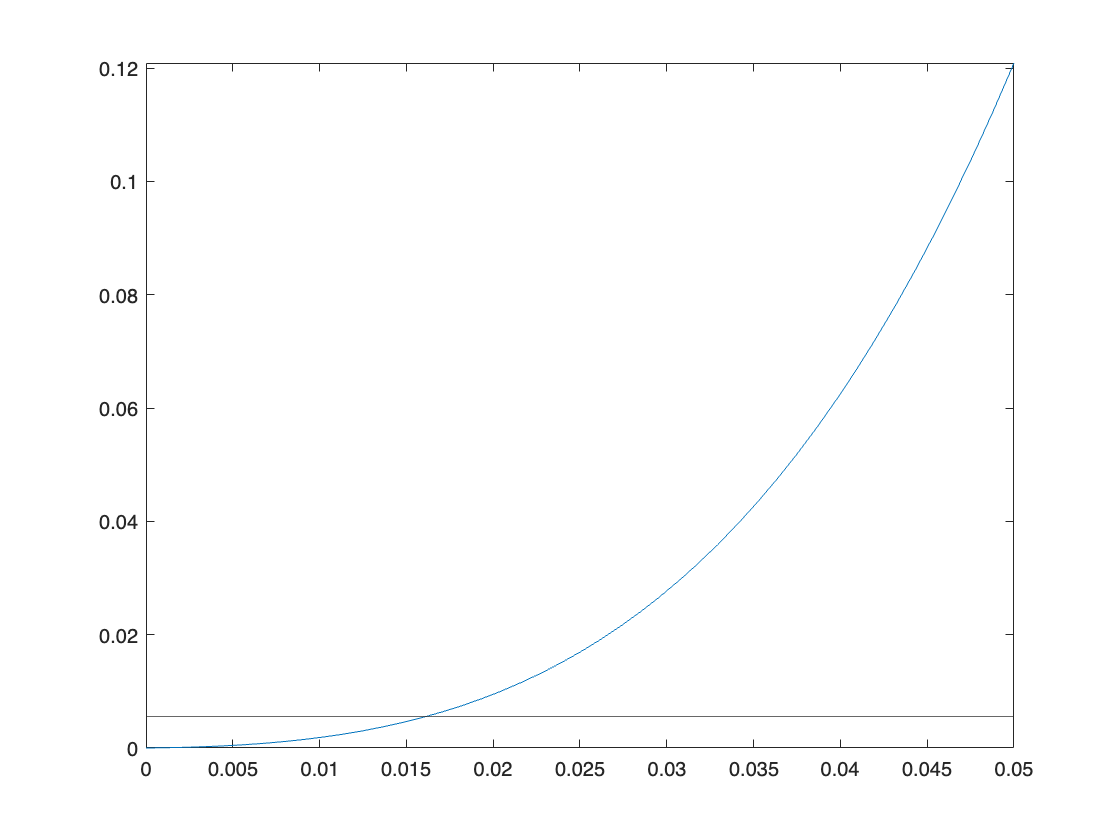

C= deflection_r4(a); %set up equation of deflection at end of swinging mass to be in terms of "a"

%SOLUTION VISUALLY%
fplot(-C,[0,0.05]) %plot the function of deflection at the end of swinging mass with range of a values from 0 to 5cm
yline(Deflection_endmass); %plot the solution line for deflection beased on input 


%SOLUTION NUMERICALLY- BASED ON SOLVING EQUATION%
solx = vpasolve(-1*C == Deflection_endmass, a); %solution to equation of deflection at end of swinging mass wrt a, where a is the cantilever beam length
solution= solx( solx>=0 ) %only accept positive values for a (ie the cantilever beam length)

$$solution = 0.016066428126778467193838197834321$$

%convert to milimeters 
solution_mm= solution*10^3 

$$solution\_mm = 16.066428126778467193838197834321$$

# Moment of inertia Equation

Function to compute the moment of inertia of a rectangular beam (about the neutral axis)

function I = MomentInertia(w, h)
        I= (1/12)*w*(h)^3;     
   
end